# DATA COMPOSITION AND ANALYSIS

By Robert Treiber III

## Compile Games

clear all

all_shots = 0;

Games = {'game3.mat','game4.mat','game5.mat','game6.mat','game7.mat', ...
    'game8.mat','game9.mat','game10.mat','game11.mat','game12.mat', ...
    'game13.mat','game14.mat','game15.mat','game16.mat','game17','game18'};

for i = 1:length(Games)
    load(string(Games(i)))
    
    for j = 1:total_shots
        all_shot_goal(all_shots+j) = shot_goal(j);
        all_shot_save(all_shots+j) = shot_save(j);
        all_shot_x_loc(all_shots+j) = shot_x_loc(j);
        all_shot_y_loc(all_shots+j) = shot_y_loc(j);
    end
    
    all_shots = all_shots + total_shots;
end

## PRINT

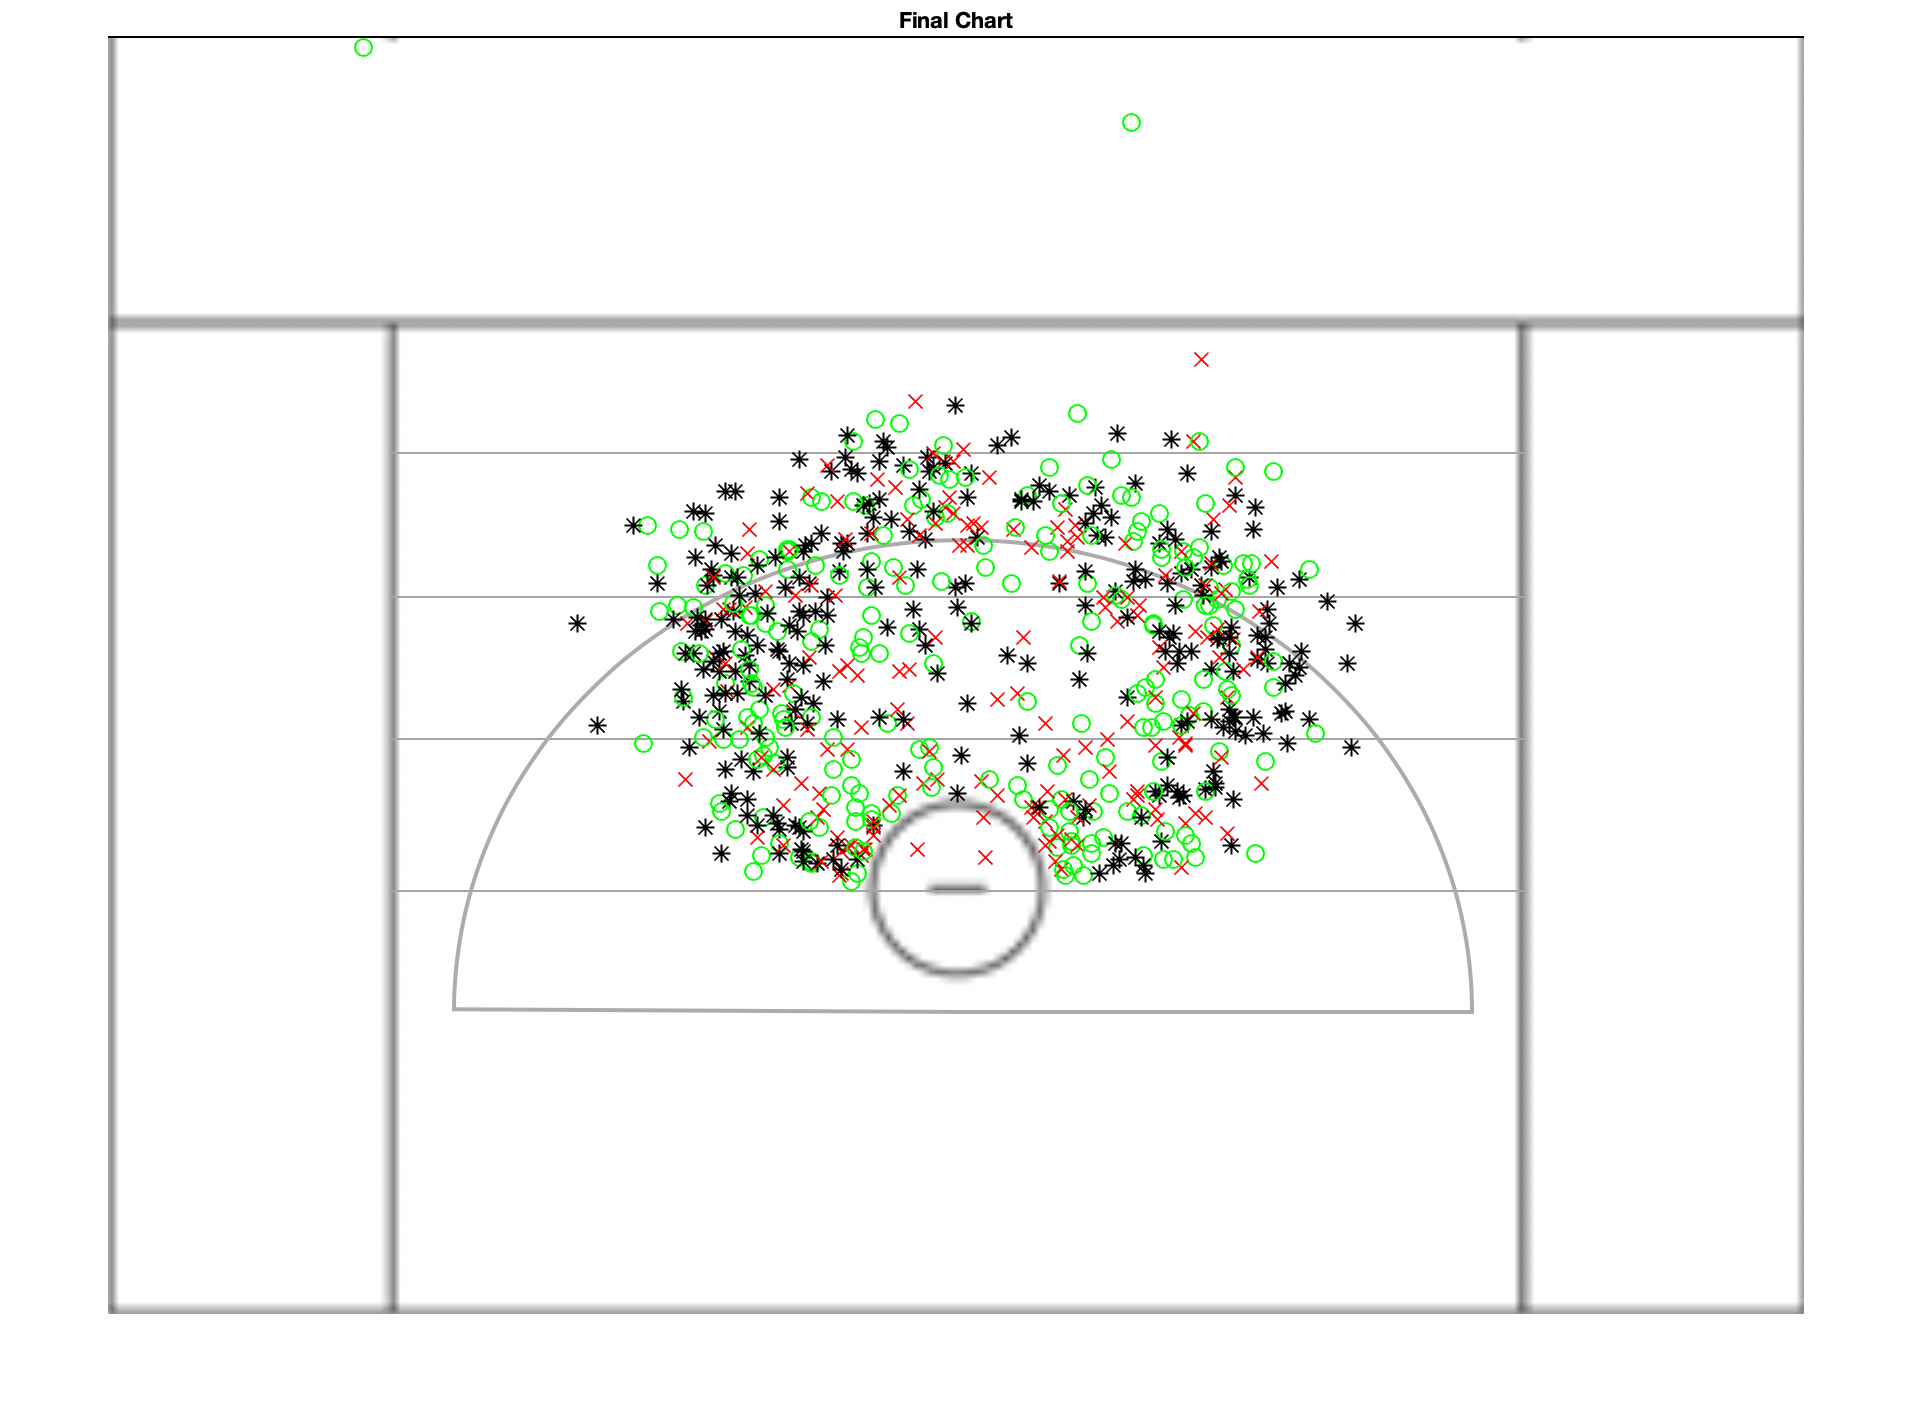

print_chart(all_shot_x_loc,all_shot_y_loc,all_shot_goal,all_shot_save,all_shots)

## IDENTIFY CENTER OF NET

This section of the asks for the user to input the location of the center of the net by clicking the location on the image of the lacrosse field

crosshair = imread('net.jpg');

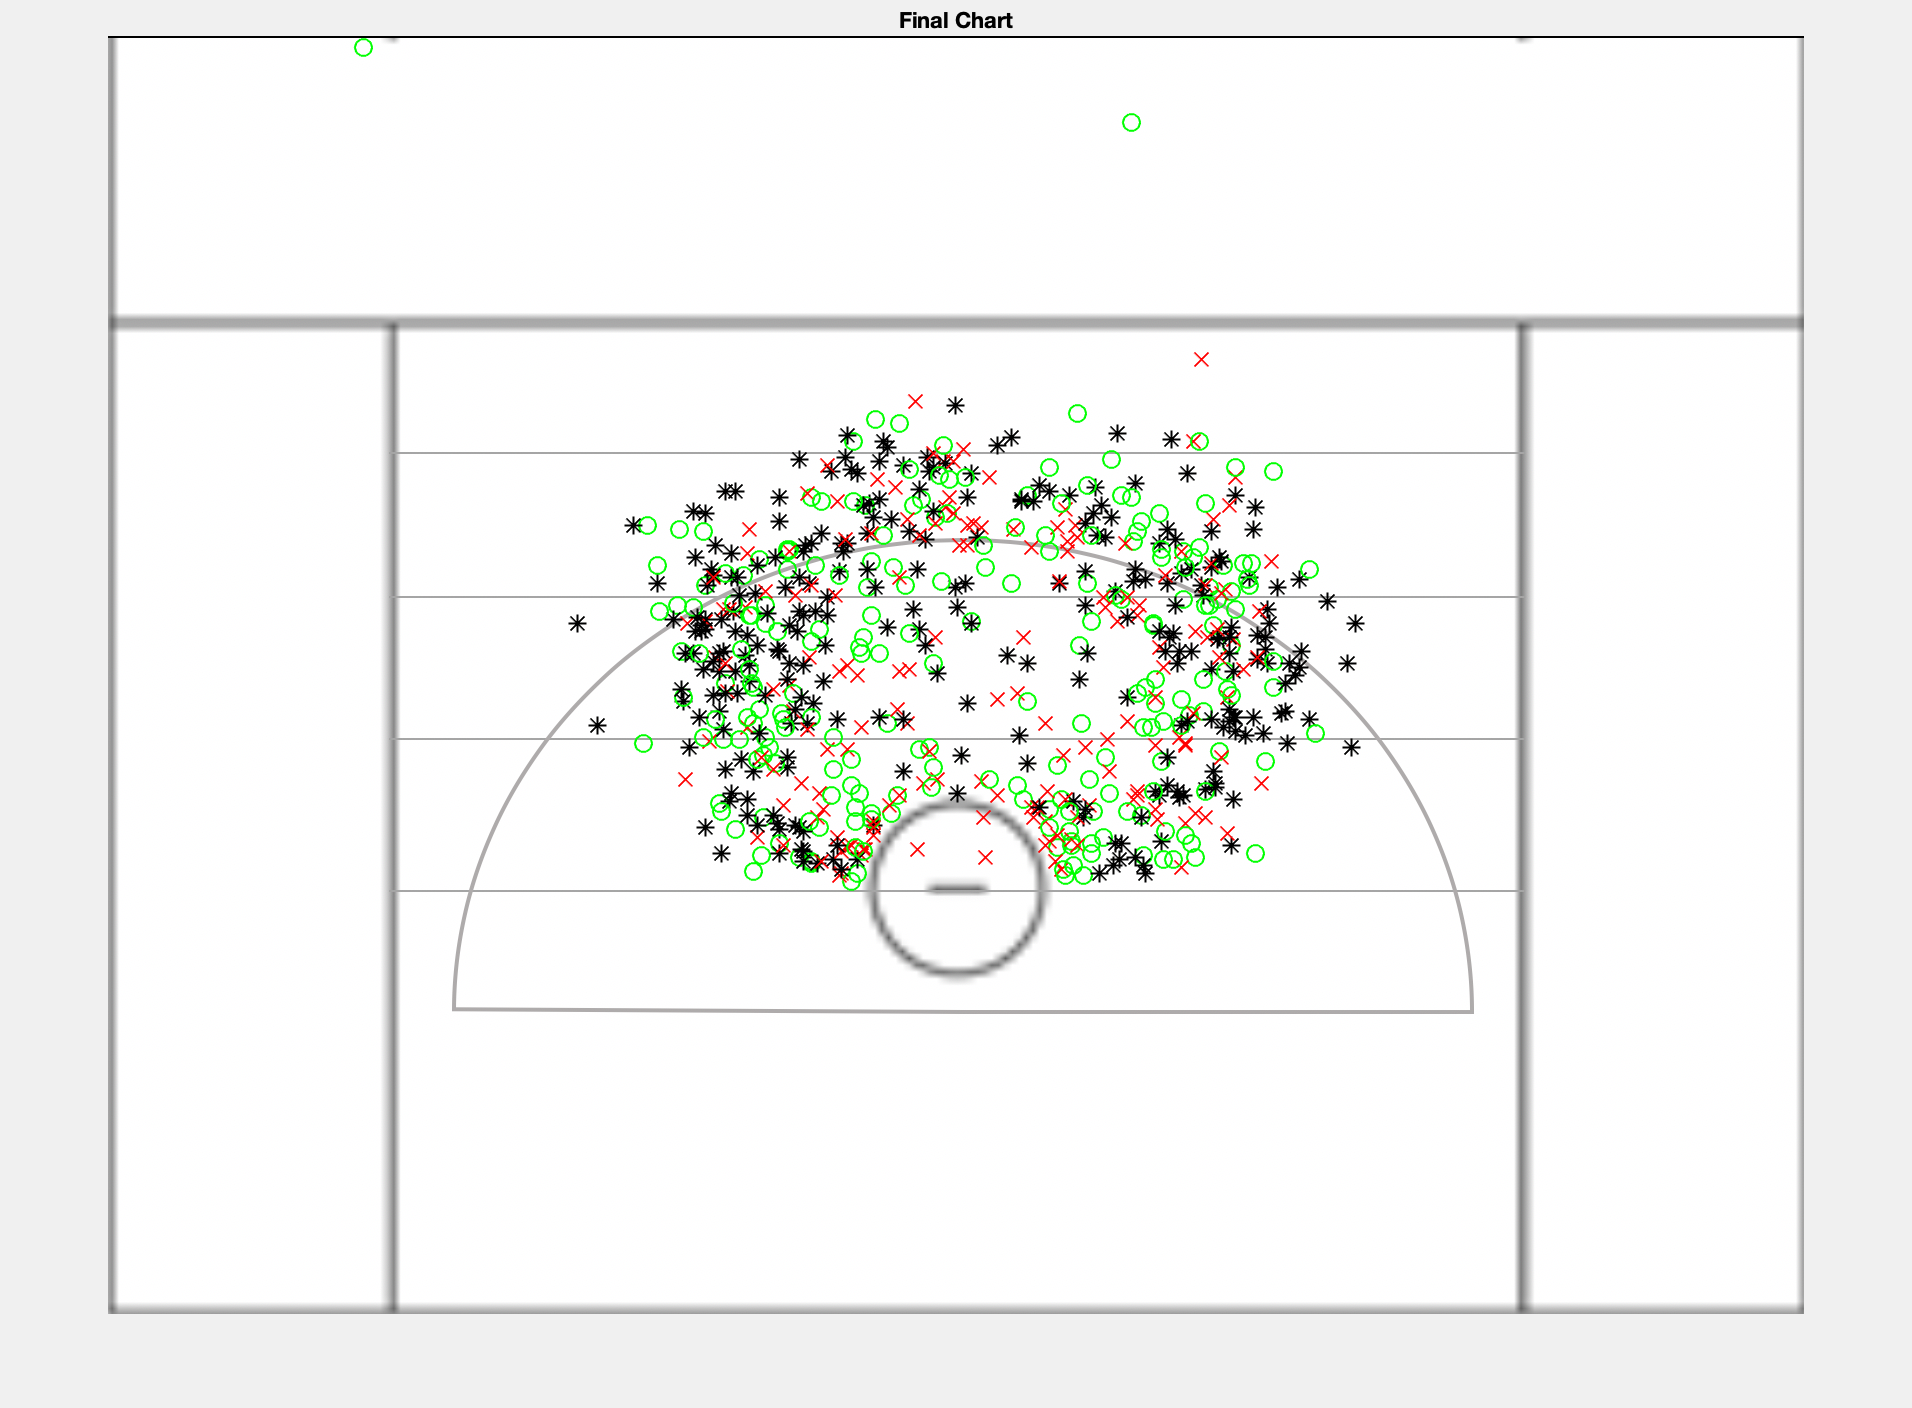

h=msgbox('Click the center of the net','Net ID','custom',crosshair);
pause(4)
if exist('h', 'var')
  delete(h);
  clear('h');
end

[x y] = ginput(1);

net_location.x = x;
net_location.y = y;

## IDENTIFY KNOWN DISTANCE

This section of the asks for the user to input the location of the restraining line (located 20 yards above the net) by clicking the location on the image of the lacrosse field

crosshair = imread('restraining_line.jpg');
h=msgbox('Click on the RESTRAINING LINE','Box ID','custom',crosshair);
pause(4)
if exist('h', 'var')
  delete(h);
  clear('h');
end

[x y] = ginput(1);

ref.x = x;
ref.y = y;

## DIST CALCULATIONS

This section uses the known distance of of 20 yards to compare how many pixels it is from the center of the net to the restaining line to find the pixels per yard ratio.  This ratio is then used to calculate the true distance, in yards, of a shot to the center of the net.

px_dist = net_location.y - ref.y;
real_dist = 20;
px_per_yrd = px_dist/real_dist;

[imx,imy] = size(field);

for i = 1:length(all_shot_x_loc)
    pix_dist(i) = sqrt((net_location.x - all_shot_x_loc(i))^2 + ...
        (net_location.y - all_shot_y_loc(i))^2);
    
    dist(i) = pix_dist(i)/px_per_yrd;
end

## ORGANIZING SHOTS BY FIELD LOCATION

This section breaks the field up into four sections for the shot locations to be placed in.

left_side = zeros(1,length(all_shot_x_loc));
left_mid = zeros(1,length(all_shot_x_loc));
right_mid = zeros(1,length(all_shot_x_loc));
right_side = zeros(1,length(all_shot_x_loc));

for i = 1:all_shots
    if (net_location.y - all_shot_y_loc(i)) < -(all_shot_x_loc(i) - net_location.x)
        left_side(i) = 1;
    elseif (net_location.y - all_shot_y_loc(i)) < (all_shot_x_loc(i) - net_location.x)
        right_side(i) = 1;
    elseif all_shot_x_loc(i) < net_location.x
        left_mid(i) = 1;
    elseif all_shot_x_loc(i) > net_location.x
        right_mid(i) = 1;
    end
end

## ORGANIZING SHOTS BY FIELD LOCATION & DISTANCE FROM NET

This section continues to divide up the field by location and distance to eventually calculate the save percentage based on location.

ls_goals = 0; ls_saves = 0; ls_misses = 0;
ls_close_goal = 0; ls_mid_goal = 0; ls_long_goal = 0;
ls_close_save = 0; ls_mid_save = 0; ls_long_save = 0;
ls_close_miss = 0; ls_mid_miss = 0; ls_long_miss = 0;

rs_goals = 0; rs_saves = 0; rs_misses = 0;
rs_close_goal = 0; rs_mid_goal = 0; rs_long_goal = 0;
rs_close_save = 0; rs_mid_save = 0; rs_long_save = 0;
rs_close_miss = 0; rs_mid_miss = 0; rs_long_miss = 0;

lm_goals = 0; lm_saves = 0; lm_misses = 0;
lm_close_goal = 0; lm_mid_goal = 0; lm_long_goal = 0;
lm_close_save = 0; lm_mid_save = 0; lm_long_save = 0;
lm_close_miss = 0; lm_mid_miss = 0; lm_long_miss = 0;

rm_goals = 0; rm_saves = 0; rm_misses = 0;
rm_close_goal = 0; rm_mid_goal = 0; rm_long_goal = 0;
rm_close_save = 0; rm_mid_save = 0; rm_long_save = 0;
rm_close_miss = 0; rm_mid_miss = 0; rm_long_miss = 0;

for i = 1:all_shots
    if left_side(i) == 1
        if all_shot_goal(i) == 1
            ls_goals = ls_goals + 1;
            if dist(i) < 6
                ls_close_goal = ls_close_goal + 1;
            elseif dist(i) < 12
                ls_mid_goal = ls_mid_goal + 1;
            else
                ls_long_goal = ls_long_goal + 1;
            end
        elseif all_shot_save(i) == 1
            ls_saves = ls_saves + 1;
            if dist(i) < 6
                ls_close_save = ls_close_save + 1;
            elseif dist(i) < 12
                ls_mid_save = ls_mid_save + 1;
            else
                ls_long_save = ls_long_save + 1;
            end
        else
            ls_misses = ls_misses + 1;
            if dist(i) < 6
                ls_close_miss = ls_close_miss + 1;
            elseif dist(i) < 12
                ls_mid_miss = ls_mid_miss + 1;
            else
                ls_long_miss = ls_long_miss + 1;
            end
        end
    elseif right_side(i) == 1
        if all_shot_goal(i) == 1
            rs_goals = rs_goals + 1;
            if dist(i) < 6
                rs_close_goal = rs_close_goal + 1;
            elseif dist(i) < 12
                rs_mid_goal = rs_mid_goal + 1;
            else
                rs_long_goal = rs_long_goal + 1;
            end
        elseif all_shot_save(i) == 1
            rs_saves = rs_saves + 1;
            if dist(i) < 6
                rs_close_save = rs_close_save + 1;
            elseif dist(i) < 12
                rs_mid_save = rs_mid_save + 1;
            else
                rs_long_save = rs_long_save + 1;
            end
        else
            rs_misses = rs_misses + 1;
            if dist(i) < 6
                rs_close_miss = rs_close_miss + 1;
            elseif dist(i) < 12
                rs_mid_miss = rs_mid_miss + 1;
            else
                rs_long_miss = rs_long_miss + 1;
            end
        end
    elseif left_mid(i) == 1
        if all_shot_goal(i) == 1
            lm_goals = lm_goals + 1;
            if dist(i) < 6
                lm_close_goal = lm_close_goal + 1;
            elseif dist(i) < 12
                lm_mid_goal = lm_mid_goal + 1;
            else
                lm_long_goal = lm_long_goal + 1;
            end
        elseif all_shot_save(i) == 1
            lm_saves = lm_saves + 1;
            if dist(i) < 6
                lm_close_save = lm_close_save + 1;
            elseif dist(i) < 12
                lm_mid_save = lm_mid_save + 1;
            else
                lm_long_save = lm_long_save + 1;
            end
        else
            lm_misses = lm_misses + 1;
            if dist(i) < 6
                lm_close_miss = lm_close_miss + 1;
            elseif dist(i) < 12
                lm_mid_miss = lm_mid_miss + 1;
            else
                lm_long_miss = lm_long_miss + 1;
            end
        end
    elseif right_mid(i) == 1
        if all_shot_goal(i) == 1
            rm_goals = rm_goals + 1;
            if dist(i) < 6
                rm_close_goal = rm_close_goal + 1;
            elseif dist(i) < 12
                rm_mid_goal = rm_mid_goal + 1;
            else
                rm_long_goal = rm_long_goal + 1;
            end
        elseif all_shot_save(i) == 1
            rm_saves = rm_saves + 1;
            if dist(i) < 6
                rm_close_save = rm_close_save + 1;
            elseif dist(i) < 12
                rm_mid_save = rm_mid_save + 1;
            else
                rm_long_save = rm_long_save + 1;
            end
        else
            rm_misses = rm_misses + 1;
            if dist(i) < 6
                rm_close_miss = rm_close_miss + 1;
            elseif dist(i) < 12
                rm_mid_miss = rm_mid_miss + 1;
            else
                rm_long_miss = rm_long_miss + 1;
            end
        end
    end
end

percent_left_side_goals = ls_goals / nnz(left_side);
percent_left_side_saves = ls_saves / nnz(left_side);
percent_right_side_goals = rs_goals / nnz(right_side);
percent_right_side_saves = rs_saves / nnz(right_side);
percent_left_mid_goals = lm_goals / nnz(left_mid);
percent_left_mid_saves = lm_saves / nnz(left_mid);
percent_right_mid_goals = rm_goals / nnz(right_mid);
percent_right_mid_saves = rm_saves / nnz(right_mid);

## SAVE PERCENTAGES BY LOCATION AND DISTANCE

save_percentage_left_side = ls_saves / (ls_saves+ls_goals);
save_percent_ls_close = ls_close_save / (ls_close_save+ls_close_goal);
save_percent_ls_mid = ls_mid_save / (ls_mid_save+ls_mid_goal);
save_percent_ls_long = ls_long_save / (ls_long_save+ls_long_goal);

save_percentage_right_side = rs_saves / (rs_saves + rs_goals);
save_percent_rs_close = rs_close_save / (rs_close_save+rs_close_goal);
save_percent_rs_mid = rs_mid_save / (rs_mid_save+rs_mid_goal);
save_percent_rs_long = rs_long_save / (rs_long_save+rs_long_goal);

save_percentage_left_mid = lm_saves / (lm_saves+lm_goals);
save_percent_lm_close = lm_close_save / (lm_close_save+lm_close_goal);
save_percent_lm_mid = lm_mid_save / (lm_mid_save+lm_mid_goal);
save_percent_lm_long = lm_long_save / (lm_long_save+lm_long_goal);

save_percentage_right_mid = rm_saves / (rm_saves + rm_goals);
save_percent_rm_close = rm_close_save / (rm_close_save+rm_close_goal);
save_percent_rm_mid = rm_mid_save / (rm_mid_save+rm_mid_goal);
save_percent_rm_long = rm_long_save / (rm_long_save+rm_long_goal);

## HEAT MAP

Produces a heatmap to visualize save percentages based on location

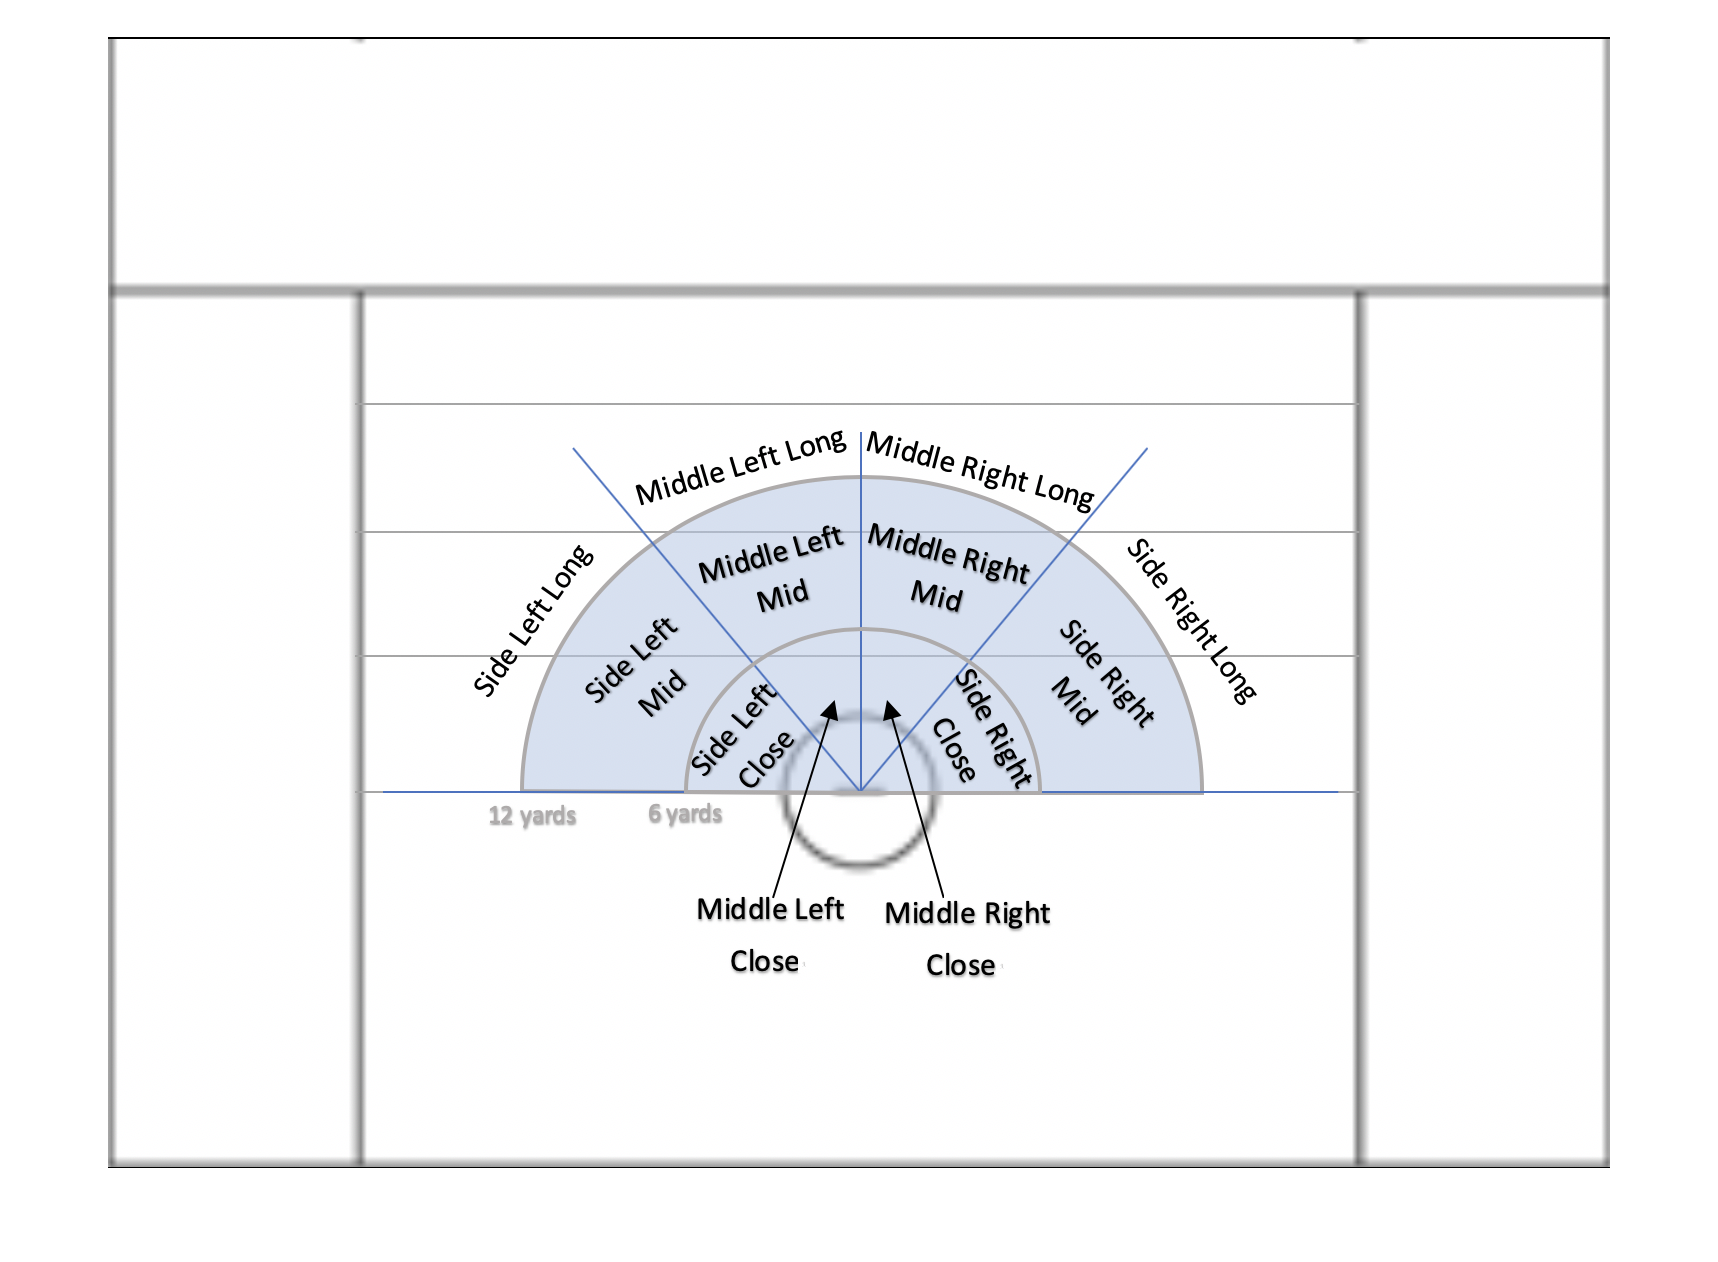

save_perc = [save_percent_ls_long, save_percent_lm_long, save_percent_rm_long, save_percent_rs_long; ...
    save_percent_ls_mid, save_percent_lm_mid, save_percent_rm_mid, save_percent_rs_mid; ...
    save_percent_ls_close, save_percent_lm_close, save_percent_rm_close, save_percent_rs_close];

location = {'Side Left', 'Middle Left', 'Middle Right', 'Side Right'};
distances = {'Long', 'Mid', 'Close'};

figure
imshow('field_locations.png')


figure
h = heatmap(location, distances, save_perc)

h =   HeatmapChart with properties:

        XData: {4×1 cell}
        YData: {3×1 cell}
    ColorData: [3×4 double]

  Show all properties

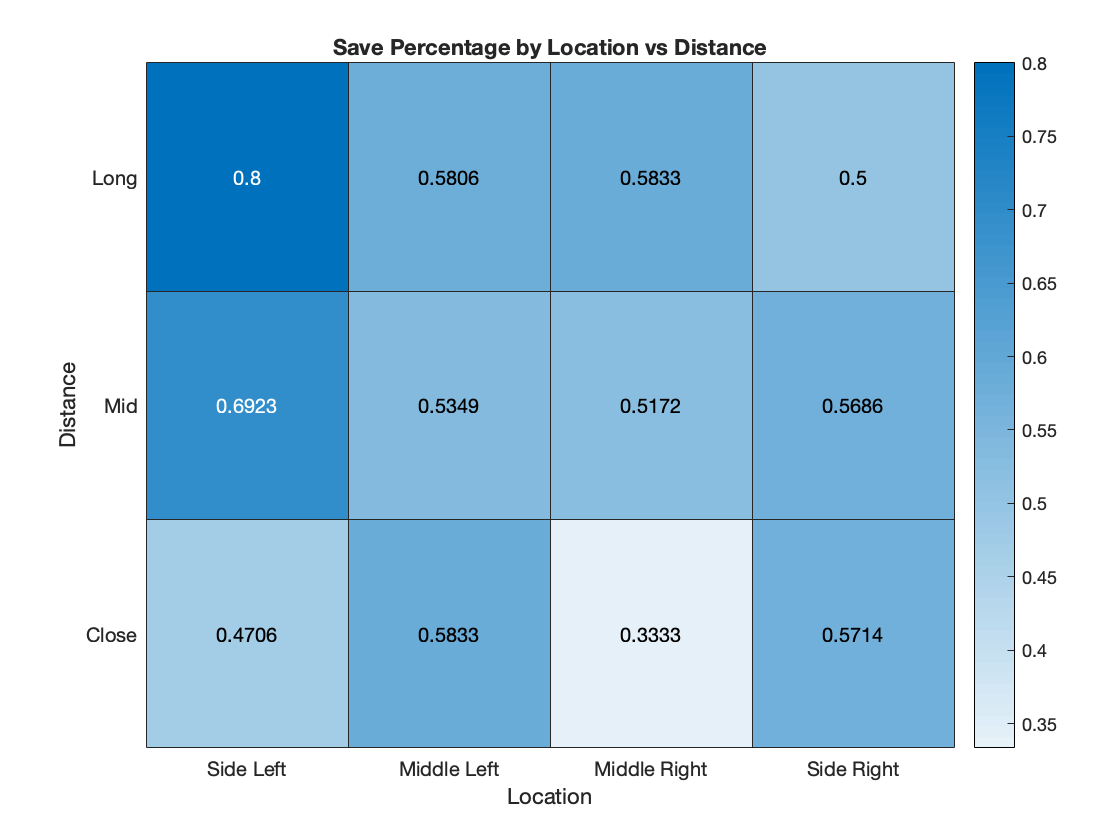


h.Title = 'Save Percentage by Location vs Distance';
h.XLabel = 'Location';
h.YLabel = 'Distance';

## CLEANING DATA FOR MACHINE LEARNING

This section makes tables to allow the machine learning functions and toolboxes easier to manipulate/ run

for i = 1:all_shots
    if all_shot_goal(i) == 1 && all_shot_save(i) == 0
        shot_type(i) = -1;
        all_shot_miss_or_save(i) = 0;
    elseif all_shot_goal(i) == 0 && all_shot_save(i) == 1
        shot_type(i) = 1;
        all_shot_miss_or_save(i) = 1;
    else
        shot_type(i) = 0;
        all_shot_miss_or_save(i) = 1;
    end
end

data_table = table(shot_type', all_shot_x_loc', all_shot_y_loc', dist');

data_table_NEW = table(all_shot_miss_or_save', all_shot_save', all_shot_goal', all_shot_x_loc', all_shot_y_loc', dist');


## MACHINE LEARNING ANALYSIS

The first analysis used the Regression Learner Toolbox. My response variable was a logical variable that was true if the shot missed the net or was saved. Var5, on the x-axis represents the shot distance, in yards, from from the center of the net. It is interesting to not that the regression line would not predict a save or miss for certain until the shot occurs from outside of 20 yards. This makes sense bcasuse the model does not account for a specific circumstance where the goalie was not in the net, therefore allowing a goal from a distance that we would logically not expect.

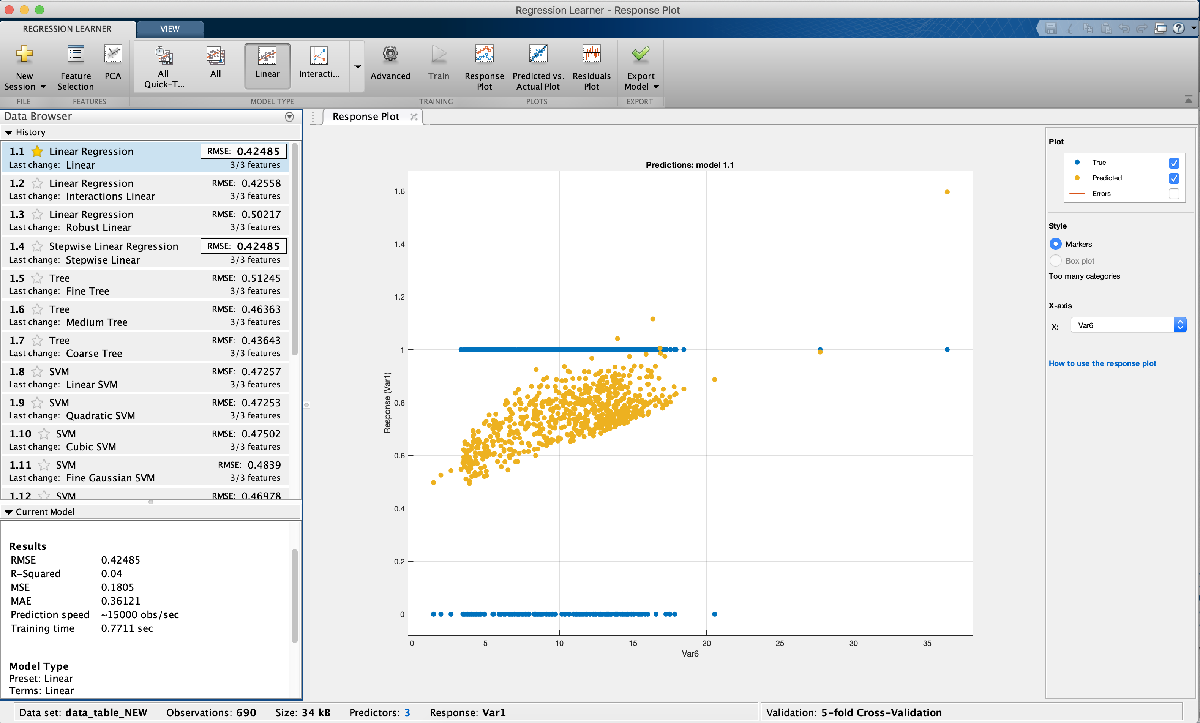

The second analysis used the Classification Learner Toolbox. After running all the models in the toolbox, the Logistic Regression was identified as the best model. Although the model identified 75% accuracy, I don't believe that this is useful analysis. There were 174 goals, 225 saves, and 291 misses; therere a miss or a save happened 74.78% of the time. Essencially this means that at certain distance the model realized it was more advantageous to guess a save/ miss than a goal. 

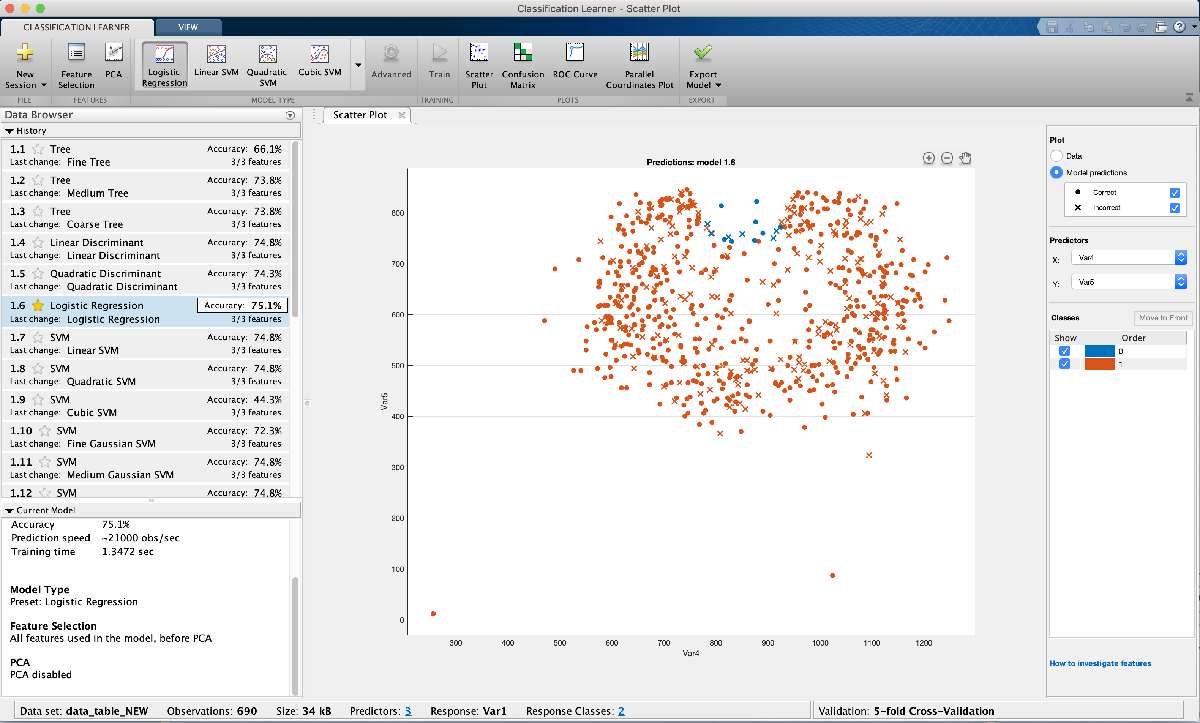

## **DATASHEET**

**Motivation for Dataset Creation**

This dataset was created over the course of an entire lacrosse season.  I serve as a graduate assistant goalie coach for the Tufts Men’s Lacrosse Team and during the game am responsible for tracking opponents’ shot location and results.  I have always been interested in baseball and basketball sabermetrics, a combination of statistics and mathematical analysis, in the form of shot charts, strike zone charts, and any metrics that can produce heatmaps.  Currently, the NBA and MLB are leading the push for data driven decisions for players and coaches. Moneyball is a famous book that tells the tale of how the Oakland Athletics, a small market baseball organization in the MLB, used sabermetrics to compete with premier market teams, like the Boston Red Sox and New York Yankees.

My data was originally recorded, during the games, by hand and needed to be translated into digital data that could be cleaned, manipulated, and analyzed.  Because I needed to create my own data entry program, I tried to create a program that could be manipulated to be used for any sport, not just lacrosse.  Ultimately, I wanted to see if sabermetrics could be applied to lacrosse and help with defensive decision making and game planning.

**Dataset Composition**

One of the main differences between lacrosse and basketball is that in lacrosse when there is a shot, there is an addition possible outcome to a goal or miss, a save.  After entering each game’s data individually, I was able to compile the data into one shot chart for the season and calculate the total saves, goals, and misses totaling 690 different shots.  Each shot has an x & y location of the field and then the shot type.

**Data Collection Process**

The data was collected in real-time by me during the games.  A lacrosse game consists of four, fifteen-minute quarters, and overtime, if necessary.  Each game I would print a new shot chart and record the location and type of each shot as it occurred.  To this date, our season has included eighteen games, which includes the regular season, league playoffs and the first round of NCAA playoffs.  It should be noted that blocked or deflected shots were counted as missed shots.  Ultimately, the data represents all of the shots that opponents took while trying to score on us, to this date.  I believe that there is some possibility for error/ noise when looking at the shot locations.  While I did my best to approximate the exact location of the shot, there is a high probability that they are not recorded or entered into the program exactly where the shot occurred.  In the future it, might be worth re-watching the games to confirm the shot locations because the camera that is used to film has a high vantage point than where I am positioned on the sideline.

**Data Processing**

During the data entry portion of my project, each game was saved individually as raw data consisting of the x & y pixel location of the shot on image and the type of shot.  Cleaning the data was required to translate the pixel location of the shot to a distance in yards from the net.  I used MATLab to enter/ convert my data from pen and paper into digital data and to analyze the data through machine learning toolboxes. 

**Dataset Maintenance**

The dataset will continue to be updated as long as I am coaching.  I will offer this program and data to the current and future coaches if they would like to continue to build, use and analyze the data.  I will also offer my program online to others so that they may improve it and use it for their own analysis.